tableN = readtable("si_anode.csv");
cVecN = table2array(tableN(:,"capacity"));
vVecN = table2array(tableN(:,"voltage"));

[thetaVecN, vThetaVecN] = normalizeCapacity(cVecN, vVecN);

tablePNMC = readtable("nmc_cathode.csv");
cVecP = table2array(tablePNMC(:,"capacity"));
vVecP = table2array(tablePNMC(:,"voltage"));

[thetaVecP, vThetaVecP] = normalizeCapacity(cVecP, vVecP);

%plot(thetaVecN, vThetaVecN, 'r--', thetaVecP, vThetaVecP, 'b--')

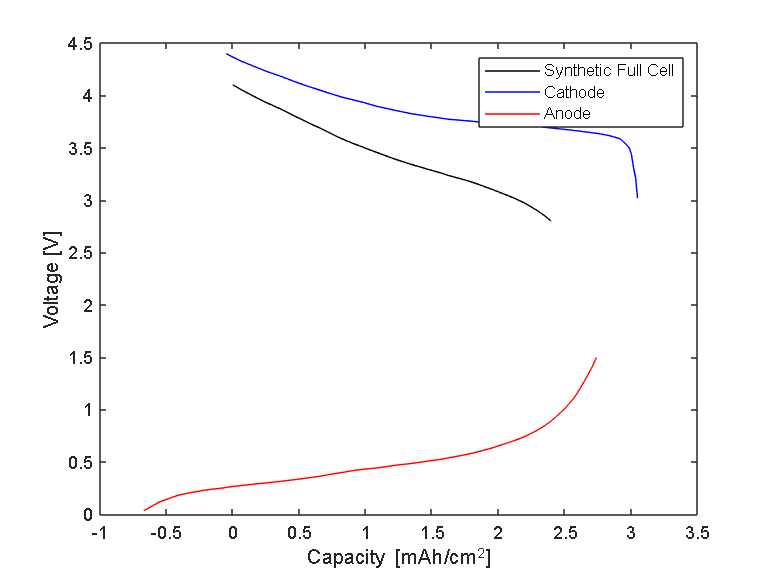

cEff = 0.996;
chargeDir = "dchg";
vMin = 2.8; % V
vMax = 4.1; % V

npRatio = 1.1;
cNFresh = 3.41; % mAh/cm^2
cPFresh = cNFresh / npRatio; % mAh/cm^2
x0Fresh = 0;
y0Fresh = 0.9;

[~, ~, cLiFresh] = compInvFromESOH(cNFresh, cPFresh, x0Fresh, y0Fresh);

[cVecNModel, vVecNModel, cVecPModel, vVecPModel, cVecFullModel, vVecFullModel] = combineHalfCells(thetaVecN, ...
    vThetaVecN, thetaVecP, vThetaVecP, cNFresh, cPFresh, x0Fresh, y0Fresh, vMin, vMax, chargeDir);
figure(1)
plotHalfCellModel(cVecNModel, vVecNModel, cVecPModel, vVecPModel, cVecFullModel, vVecFullModel, "-")
legend(["Synthetic Full Cell", "Cathode", "Anode"])
title("")

% Determine capacity fade
anodePorosity = 0.35;
anodeDensity = 1.13; % g/cm^3
anodeLoading = 4.112; % mg/cm^2
anodeElyteV = anodeLoading/1000/anodeDensity*anodePorosity; % mL/cm^2

cLiVec = cLiFresh;
cNVec = cNFresh;
cPVec = cPFresh;
x0Vec = x0Fresh;
y0Vec = y0Fresh;
cFullVec = max(cVecFullModel);
anodeElyteVVec = anodeElyteV;

LLIPerCycle = lithiumLoss(cEff);
LAMnPerCycleVec = [];


% Loop over 100 cycles
for i = 1:100
    [LAMnPerCycle, newAnodeElyteV] = anodeLoss(cEff, cFullVec(i), anodeElyteVVec(i));
    newCN = cNVec(i) - cNVec(i) * LAMnPerCycle;
    newCLi = cLiVec(i) - cLiVec(i) * LLIPerCycle;
    [~, ~, newX0, newY0] = esohFromCompInv(newCN, cPVec(i), newCLi);

    [cVecNModel, ~, cVecPModel, ~, cVecFullModel, ~] = combineHalfCells(thetaVecN, vThetaVecN, ...
        thetaVecP, vThetaVecP, newCN, cPVec(i), newX0, newY0, vMin, vMax, chargeDir);

    cLiVec = [cLiVec newCLi];
    cNVec = [cNVec newCN];
    cPVec = [cPVec cPVec(i)];
    x0Vec = [x0Vec newX0];
    y0Vec = [y0Vec newY0];
    cFullVec = [cFullVec max(cVecFullModel)];
    anodeElyteVVec = [anodeElyteVVec newAnodeElyteV];
    LAMnPerCycleVec = [LAMnPerCycleVec LAMnPerCycle];

end

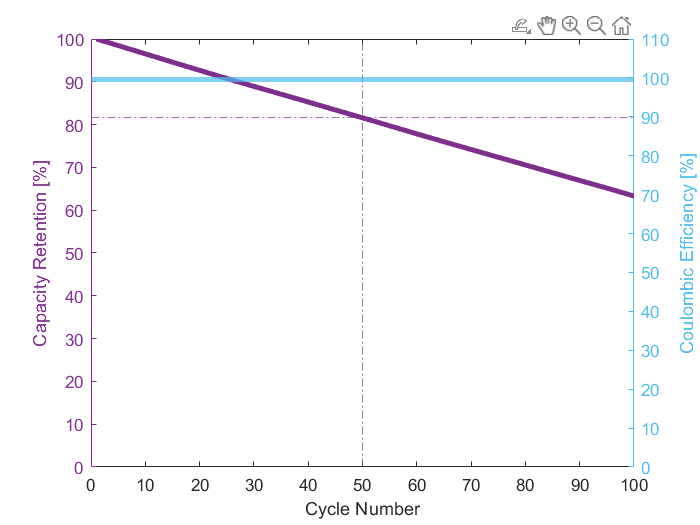

capRetention = cFullVec / max(cFullVec) *100;

figure(2)
yyaxis("left")
plot(capRetention, color="#7E2F8E", LineWidth=3)
ylabel("Capacity Retention [%]")
xlabel("Cycle Number")
ylim([0,100]);
xlim([0,100]);
ax = gca;
ax.YColor = "#7E2F8E";
yline(capRetention(50), "-.", color="#7E2F8E")
xline(50, "-.", color="#7E2F8E")

yyaxis("right")
yline(cEff*100, color="#4DBEEE", LineWidth=3)
ylim([0,110]);
ylabel("Coulombic Efficiency [%]")
ax = gca;
ax.YColor = "#4DBEEE";

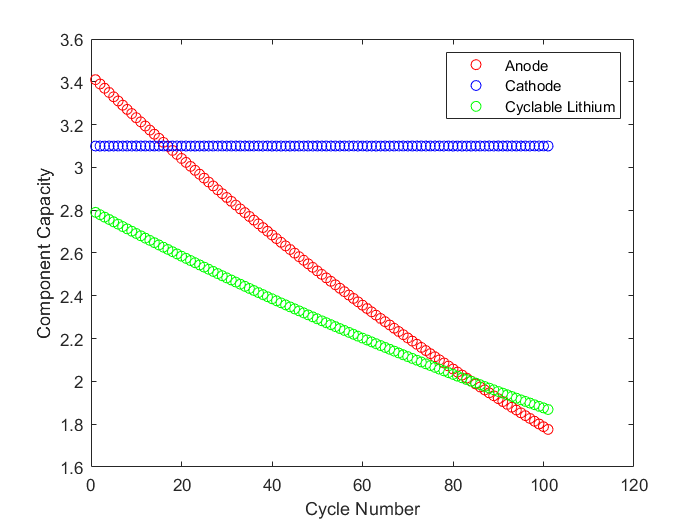


figure(3)
plot(cNVec, "ro")
hold on
plot(cPVec, "bo")
plot(cLiVec, "go")
ylabel("Component Capacity")
xlabel("Cycle Number")
legend(["Anode", "Cathode", "Cyclable Lithium"])
hold off

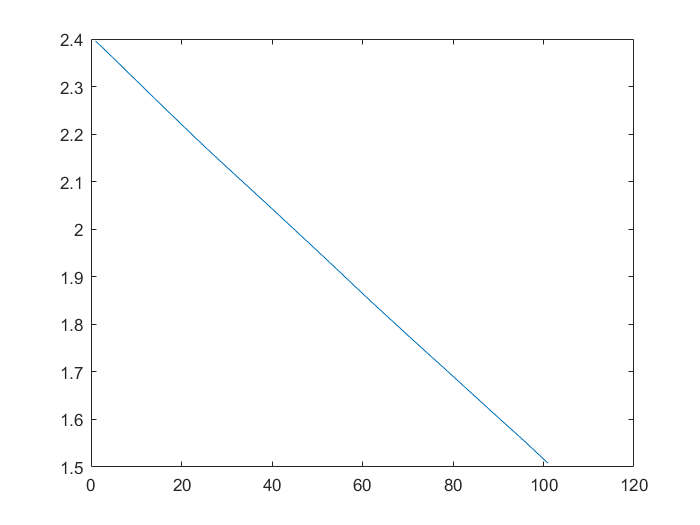


figure(4)
plot(cFullVec)